# 실습#1: 이체운동(Two-Body Dynamics)

**[2024-가을] 우주비행역학(ASE3080), 인하대학교 항공우주공학과**

**목성훈(shmok@inha.ac.kr)**

% 초기화
clear all; 
close all;
clc;
format long

### 1. TLE 정보를 이용한 SGP4 기반 궤도 전파

#### 1.1 시뮬레이션 환경

위성 시나리오(satellite scenario)를 생성합니다. 적분 간격 등을 함께 설정합니다.

startTime = datetime(2020,5,11,12,35,38);
simulationDuration = 2;   
stopTime = startTime + days(simulationDuration);
sampleTime = 60;
sc = satelliteScenario(startTime, stopTime, sampleTime);

#### 1.2 이체 운동 기반 전파

이체 역학 기반(케플러 운동)으로 궤도를 전파합니다.

tleFile = "eccentricOrbitSatellite.tle";
satTwoBodyKeplerian = satellite(sc,tleFile, ...
    "Name","satTwoBodyKeplerian", ...
    "OrbitPropagator","two-body-keplerian");
show(satTwoBodyKeplerian);
groundTrack(satTwoBodyKeplerian);

#### 1.3 SGP4 기반 궤도 전파

satSGP4 = satellite(sc,tleFile, ...
    "Name","satSGP4", ...
    "OrbitPropagator","sgp4");
satSGP4.MarkerColor = "green";
satSGP4.Orbit.LineColor = "green";
satSGP4.LabelFontColor = "green";

두 전파기 결과를 비교합니다.

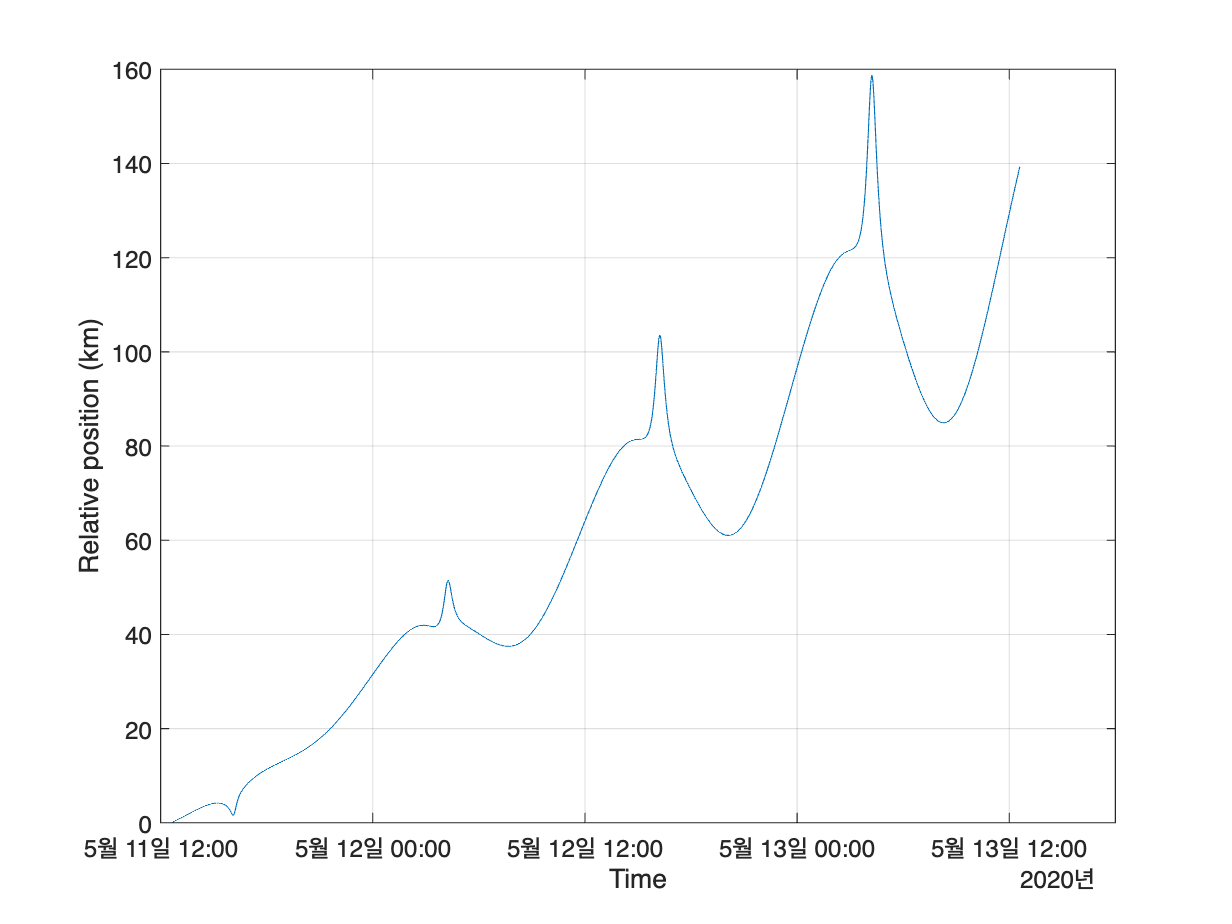

[positionTwoBodyKeplerian,velocityTwoBodyKeplerian,time] = states(satTwoBodyKeplerian);
[positionSGP4,velocitySGP4] = states(satSGP4);
sgp4RelativePosition = vecnorm(positionSGP4 - positionTwoBodyKeplerian,2,1);
sgp4RelativePositionKm = sgp4RelativePosition/1000;
plot(time,sgp4RelativePositionKm)
xlabel("Time")
ylabel("Relative position (km)")
grid on

### 2. ISS 궤도 예제

startTime = datetime(2023,5,11,12,35,38);
simulationDuration = 2;   
stopTime = startTime + days(simulationDuration);
sampleTime = 60;
sc = satelliteScenario(startTime, stopTime, sampleTime);
% sc = satelliteScenario;
tleFile = "ISS.tle";
% tleStruct = tleread('ISS.tle');
satISS = satellite(sc,tleFile, ...
    "Name","satISS", ...
    "OrbitPropagator","sgp4");
show(satISS);
groundTrack(satISS);